# EE170A: Project 1

Alexandre Leon 504941684 part 1.

## `Part 1: Gaussian curve fitting`

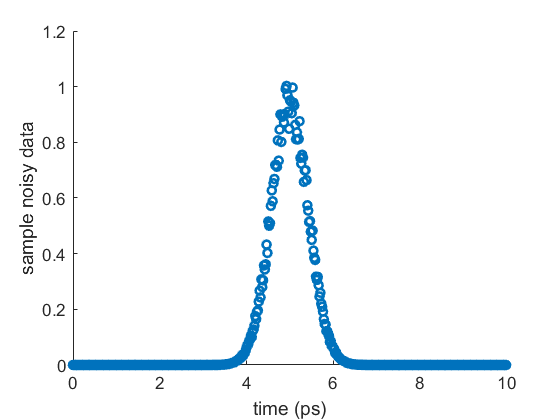

Gaussian_noise_time; %import the data

Our objective is to fit a Gaussian curve through the data set to obtain the parameters $\mathrm{the}\;\mathrm{mean}\;\mu \;,\mathrm{standard}\;\mathrm{deviation}\;\sigma \;\mathrm{and}\;\mathrm{amplitude}\;A$.

We employ the technique outlined by Hongwei Guo in the article *A Simple Algorithm for Fitting a Gaussian Function.*

The Gaussian function has the form


$$y = Ae^{-(x-\mu)^2 /2\sigma^2}$$


The approach require we take the natural logarithm to reveal a more practical expression.


$$ln(y) = ln(A) + \frac{-(x-\mu)^2}{2\sigma^2} = a + bx + cx^2
$$


This yields a parabola which can be fitted to the logarithm of a gaussian.

We can identify the parameters using the formulae

$\mu = \frac{-b}{2c}$ , $\sigma = \sqrt\frac{-1}{2c}$ and $A = e^{a - b^2/4c}$

which are computed by the function computeGaussian.

Our gaussian signal is contaminated with noise, therefore to fit the curve, we use an iterative approach to approximate a,b and c as detailed in the paper


$$\left[ {\begin{array}{cc}
   \sum y^2_{k-1} & \sum xy^2_{k-1} & \sum x^2y^2_{k-1} \\
    \sum xy^2_{k-1} & \sum x^2y^2_{k-1 & \sum x^3y^2_{k-1} \\
\sum x^2y^2_{k-1} & \sum x^3y^2_{k-1} & \sum x^4y^2_{k-1}
  \end{array} } \right]

\times \left[ {\begin{array}{cc}
a_{k} \\
b_k \\
c_k
\end{array} } \right] = \left[ {\begin{array}{cc}
\sum y^2_{k-1}ln(\hat{y}) \\
\sum xy^2_{k-1}ln(\hat{y}) \\
\sum x^2y^2_{k-1}ln(\hat{y})
\end{array} } \right]













$$


In the program we use the notation


$$M \times params = n$$


Where $ln(\hat{y})
$ is the noisy signal given Gnew.

We apply the algorithm here. You may select the number of iterations.

iter =20; %slide to control iterations
y = Gnew; %Intialize the iterative approach
%iter = 50;
for k = 1:iter
    [M,n] = computeMatrixN(y, t, Gnew); warning off; %refresh the matrix
    params = M \n; %solve for parameters a,b,c
    y = computeY( params(1), params(2), params(3),t); %refresh y value
end
iter

iter = 20

[A,mu,sigma] = computeGaussian(params(1), params(2), params(3)) % compute the parameters

A = 1.0055

mu = 4.9933e-12

sigma = 4.2339e-13

The graph shows the resulting curve fit after number of iterations iterations of the algorithm, with the scatter plot showing the original data points

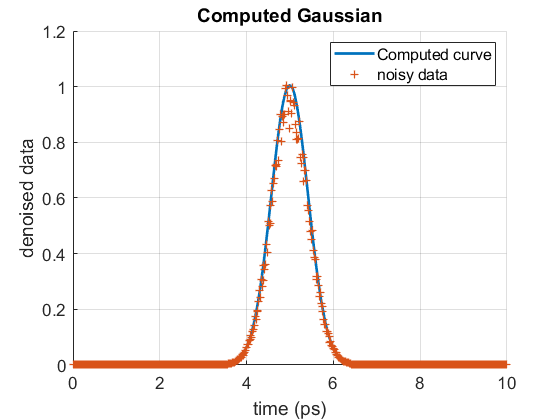


Gfound=A.*exp((-(t-mu).^(2))./(2.*(sigma.^(2))));
figure;hold on; grid on;
plot(t./10^(-12),Gfound,'Linewidth',2)
scatter(t./10^(-12),Gnew./1.068756,'+','Linewidth',1)
xlabel('time (ps)');ylabel('denoised data');set(gca,'FontSize',13); title('Computed Gaussian');
legend('Computed curve','noisy data');
hold off;

## Note

Each execution will be different as the data is regenerated every time by calling the provided script.

## Useful functions

function y = computeY(a,b,c,x) %updates y at each iteration
y = exp( a + b .*x + c.*(x.^2));
end

function [M,n] = computeMatrixN(y, x, yin) %computes the matrix M and n
lny = log(yin);
y2 = y.^2;
xy2 = x .*(y.^2);
x2y2 = (x.^2) .*(y.^2);
x3y2 = (x.^3) .*(y.^2);
x4y2 = (x.^4) .*(y.^2);
M = [ sum(y2) sum(xy2) sum(x2y2);
    sum(xy2) sum(x2y2) sum(x3y2);
    sum(x2y2) sum(x3y2) sum(x4y2)];
n = [ sum( y2 .*lny); sum( xy2 .* lny); sum(x2y2 .* lny) ];
end
    
function [A,mu,sigma] = computeGaussian(a,b,c) %extracts the necessary parameters
    mu = -b /(2*c);
    A = exp( a - (b^2)/(4*c));
    sigma = sqrt(-1/(2*c)); 
end